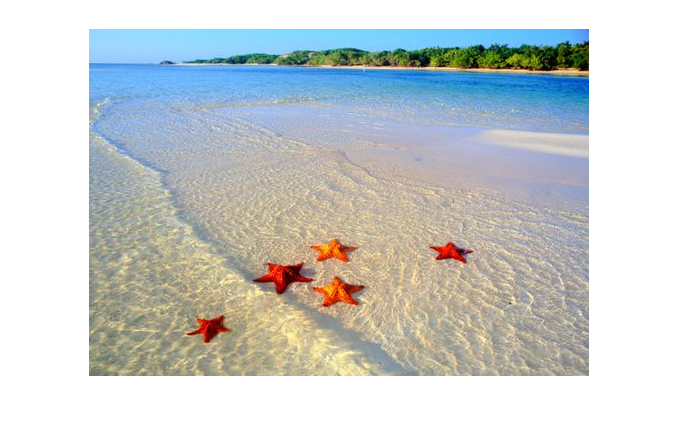

im = imread("images\starfish_5.jpg");
imshow(im)

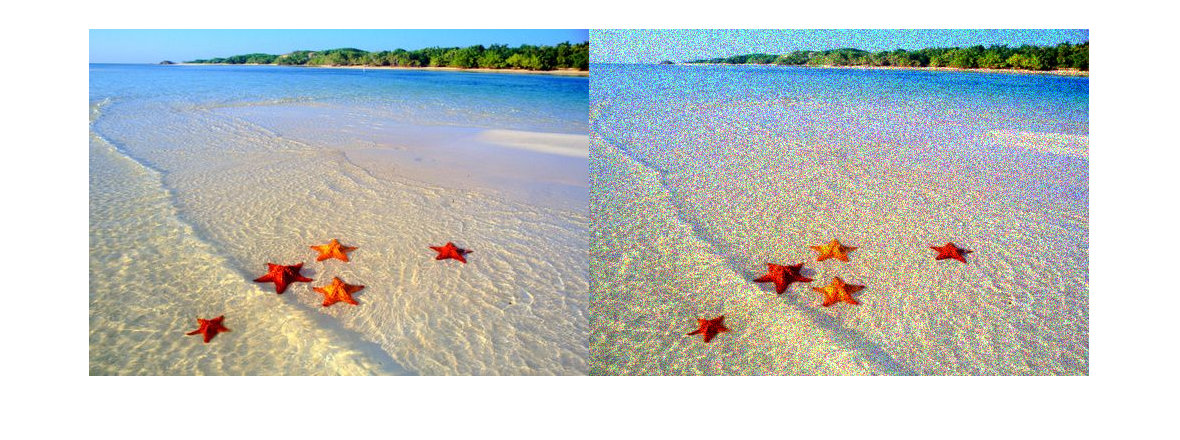

sp = imnoise(im, 'speckle');
% sp = im;
imshowpair(im, sp, 'montage')

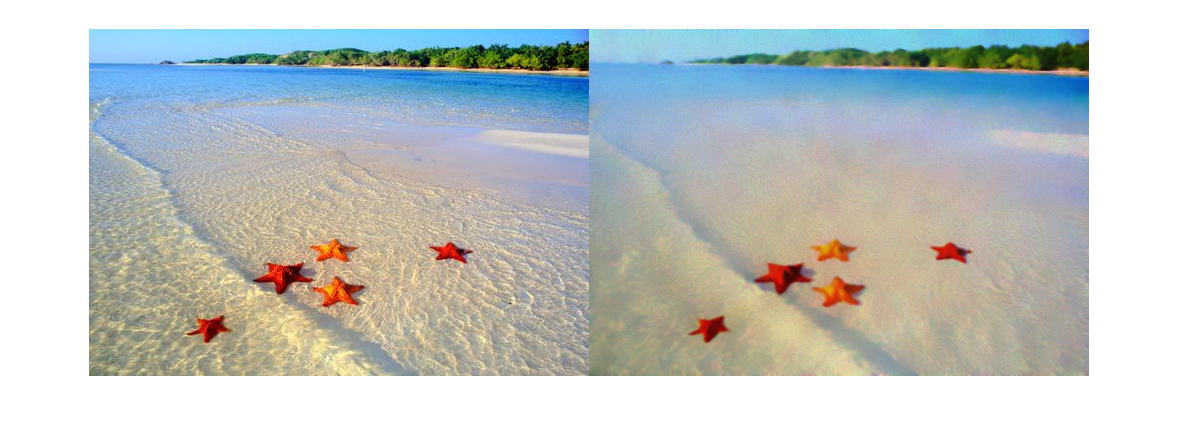

dn = DenoiseSP(sp);
imshowpair(im, dn, 'montage')

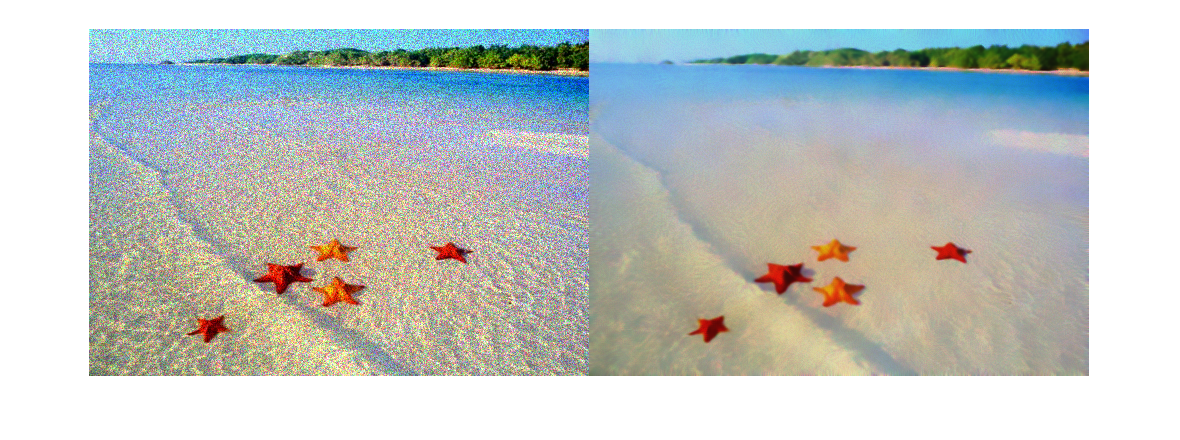

imshowpair(sp, dn, 'montage')

function [ch1, ch2, ch3] = CountImpulsePixels(im)
[ch1, ch2, ch3] = imsplit(im);
ch1 = length(find(ch1 == 0 | ch1 == 255));
ch2 = length(find(ch2 == 0 | ch2 == 255));
ch3 = length(find(ch3 == 0 | ch3 == 255));
end


function imP = DenoiseSP(im)
dims = ndims(im);

if (dims == 2)
    imP = DenoiseSP2D(im);
elseif (dims == 3)
    imP = DenoiseSP3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
end


function imP = DenoiseSP2D(im)
imP = im;
% imP = wiener2(imP,[3 3]);
% imP = imgaussfilt(imP, 2);
% imP = imsharpen(imP, 'amount', 5);

imP = imnlmfilt(im);

% % Isolate speckle and S&P noise
% filtered = medfilt2(imP, [3 3]);
% % filtered = conv2(double(im), ones(3)/9, 'same');
% imStd = std2(filtered);
% % imStd = std2(im)
% diff = abs(double(imP) - double(filtered));
% noise = (diff > 10);
% % imshow(noise)
% noise = (noise == 1);
% 
% % Swap noisy pixels for filtered ones
% denoised = imP;
% denoised(noise) = filtered(noise);
% imP = denoised;
end


function imP = DenoiseSP3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseSP2D(ch1);
dnCh2 = DenoiseSP2D(ch2);
dnCh3 = DenoiseSP2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end
